# **Chapter-3: Robot Perception**

Perception is the set of processes by which a robot converts raw sensor measurements into an internal representation of the environment and itself. Perception supports four key tasks:

- **Localization** – estimating where the robot is 

- **Mapping** – building a model of the environment 

- **Object detection** – identifying obstacles, landmarks, and free space 

- **State estimation** – estimating pose, velocity, and sensor errors 

These tasks work together to help the robot make decisions and move safely.

# **Sensors**

Sensors provide the raw data needed for perception. They are divided into two main types:

**1. Proprioceptive Sensors (Internal State)**

These measure the robot’s own motion and configuration.

- **Wheel Encoders** – measure wheel rotation for odometry 

- **IMU (Inertial Measurement Unit)** – measures acceleration and angular velocity 

**2. Exteroceptive Sensors (Environment)**

These measure the surroundings.

- **Camera** – captures images 

- **LiDAR** – measures distance using laser pulses 

- **Sonar** – uses sound waves for distance 

- **Radar** – uses radio waves for long-range detection 

- **RGB-D Camera** – provides both color and depth 

## 
$$\[
\begin{array}{|l|l|c|c|}
\hline
\textbf{General Classification (Typical Use)} &
\textbf{Sensor System} &
\textbf{PC or EC} &
\textbf{A or P} \\[4pt]
\hline
\textbf{Tactile sensors} &
\text{Contact switches, bumpers} & EC & P \\[4pt]
\text{(Detection of physical contact or closeness; security switches)} &
\text{Optical barriers} & EC & A \\[4pt]
& \text{Noncontact proximity sensors} & EC & A \\[6pt]
\hline
\textbf{Wheel/Motor sensors} &
\text{Brush encoders} & PC & P \\[4pt]
\text{(Wheel/motor speed and position)} &
\text{Potentiometers} & PC & P \\[4pt]
& \text{Synchros, resolvers} & PC & A \\[4pt]
& \text{Optical encoders} & PC & A \\[4pt]
& \text{Magnetic encoders} & PC & A \\[4pt]
& \text{Inductive encoders} & PC & A \\[4pt]
& \text{Capacitive encoders} & PC & A \\[6pt]
\hline
\textbf{Heading sensors} &
\text{Compass} & EC & P \\[4pt]
\text{(Orientation of the robot in relation to a fixed reference frame)} &
\text{Gyroscopes} & PC & P \\[4pt]
& \text{Inclinometers} & EC & A/P \\[6pt]
\hline
\end{array}
\]

\[
\text{A: active;\quad P: passive;\quad P/A: passive/active;\quad PC: proprioceptive;\quad EC: exteroceptive.}
\]
$$


## sensor characteristics

 To choose a sensor, we evaluate key properties:

- **Range:** The maximum distance a sensor can detect.

- **Field of view (FOV): **The angular extent that a sensor can perceive.

- **Resolution:** The smallest measurable change in the signal (e.g., pixel size, angular step for LiDAR).

- **Sampling rate:** Number of measurements taken per second (Hz).

- **Latency:** Time delay between sensing and data availability.

- **Noise:** Random variations in sensor readings.

- **Biases:** Systematic offset in sensor output.

- **Power and size constraints **

In practice, sensor behavior changes in real environments due to lighting, surfaces, and motion.

## In Situ Sensor Performance

Sensor characteristics can be reasonably measured in a laboratory environment with confident extrapolation to real-world performance. However, a number of important measures cannot be reliably acquired without a deep understanding of the complex interactions between environmental conditions and the sensors in question. This limitation is particularly relevant for sophisticated sensors such as active ranging devices and visual interpretation systems. 

**Sensitivity** is a desirable characteristic, measuring how an incremental change in the input (target signal) produces a corresponding change in the output. Formally, sensitivity is defined as the ratio of output change to input change. In practice, however, exteroceptive sensors often exhibit undesirable sensitivity to secondary environmental parameters, leading to performance coupling that can degrade measurement quality. **Cross-sensitivity** refers to unwanted sensitivity to environmental factors that are orthogonal to the target variable. High cross-sensitivity is generally undesirable, particularly when it cannot be modeled or compensated for. **Error** is defined as the difference between a sensor’s measured value $m$ and the true value $v$, $Error=m-v$. **Accuracy** expresses how closely a sensor’s measurement conforms to the true value and is typically given as a proportion of the true value, $Accuracy=1- \frac{|m-v|}{v}$.  Accurate assessment requires access to ground truth, which is often unavailable or difficult to determine. It is also essential to distinguish between **systematic** and **random** errors:

- **Systematic errors** arise from predictable, modelable effects such as poor calibration, or mechanical misalignment. These errors are deterministic and can be corrected through calibration or modeling.

- **Random errors** are stochastic in nature, caused by unpredictable influences such as electrical noise or lighting variations. They cannot be corrected deterministically and must be characterized statistically.

**Precision** measures the repeatability or consistency of a sensor’s output under identical conditions. High precision indicates that repeated measurements produce similar results, regardless of accuracy. A sensor can be highly precise but inaccurate if its measurements are consistently offset from the true value. If a sensor’s output is characterized by a mean value μ and a standard deviation σ, its **precision** is defined as $Precision= \frac{Output \; Range}{\sigma }

	
$.

## Characterizing Sensor Error

Mobile robots rely heavily on **exteroceptive sensors**, whose central task is to acquire information about surrounding objects so that the robot may interpret its environment. These objects are always perceived relative to the robot’s **local reference frame**, and as the robot moves, its position and motion strongly influence sensor behavior. Consequently, the nature of sensor error in a mobile platform often diverges significantly from the idealized characterization. 

**Blurring of Systematic and Random Errors**

Active ranging sensors frequently exhibit failure modes that depend on the relative geometry between the sensor and environmental surfaces. 

For example, an ultrasonic sensor can produce **specular reflections** when facing a smooth wall, resulting in grossly inaccurate range readings at specific incidence angles. As the robot moves, these relative angles vary in a seemingly stochastic fashion, making the observed errors appear **random**. 

**Multimodal Error Distributions**

Sensor error is often modeled as a random variable with an associated **probability density function (PDF)**, typically assumed to be **zero-mean, symmetric, and unimodal (Gaussian)**. These assumptions simplify mathematical treatment but are frequently violated in real-world scenarios.

Consider a sonar sensor:

- When reflections are properly received, the sensor behaves linearly with small random timing errors, producing an approximately Gaussian error profile.

- When the sound wave reflects coherently away from the sensor, **multipath echoes** cause **gross overestimation** of range. In this case, the error distribution becomes **asymmetric** and **bimodal**, as the sensor alternates between valid and invalid measurement modes.

# **Sensor Uncertainty**

As discussed previously, sensors are imperfect devices subject to both **systematic** and **random** errors. Random errors, in particular, cannot be eliminated through calibration and thus represent the fundamental level of **sensor uncertainty**. When multiple uncertain sensors are combined, their collective uncertainty must be modeled quantitatively. To achieve this, we describe the **error** of a sensor as a random variable. Let a sensor produce $n$ measurements $p_1
	

,p_2
	

,\ldots,p


_n
	
$ of some true but unknown value $X$. We define the **expected value (mean)** of the random variable $X$as $E[X]= \frac{1}{n} \sum_{i=1}^{n}{p_i}$. Here, $E[X]$ represents the best estimate of the true value based on the available noisy measurements. The statistical behavior of $X$ is characterized by its **probability density function (PDF) **$f(x)$, which defines, for each possible value $x$, the relative likelihood of occurrence. The total probability across all possible values must be unity: $\int_{-\infty }^\infty f(x)dx=1$. The probability that $X$ ies within a range $[a,b]$ is given by $P[a<X<b]=\int _a^bf(x)dx$. From $f(x)$, we can compute the followingfundamental quantities:

- Mean value (expected value): $E[X]=\int_{-\infty }^\infty xf(x)dx$

- Variance and standard deviation: $Var(X)=\sigma ^2=E[(X-E[X])^2]$, $\sigma =\sqrt{ Var(X)}
$

**The Gaussian Distribution**

In robotics, the most common model for random error is the **Gaussian (normal) distribution: **$f(x)=\frac{1}{\sigma \sqrt{2\pi }} exp(- \frac{(x-\mu )^2}{2\sigma ^2})$, where $𝜇$ s the **mean value**, $\sigma $ is the **standard deviation. **

## **Optical Encoders**

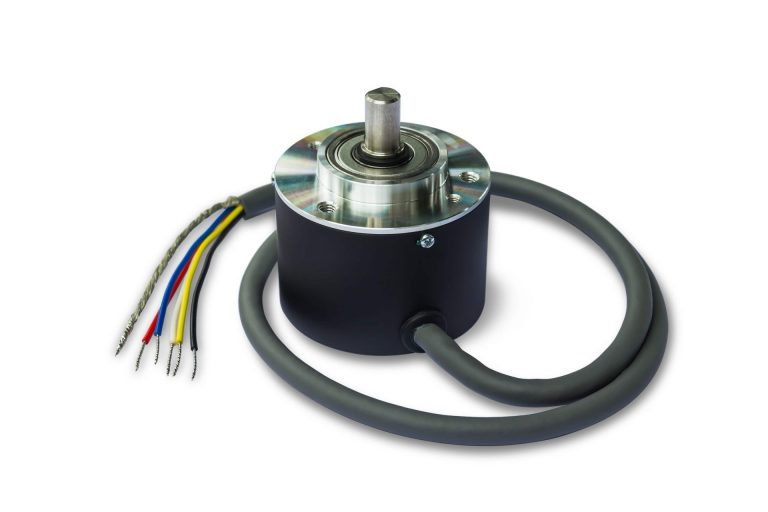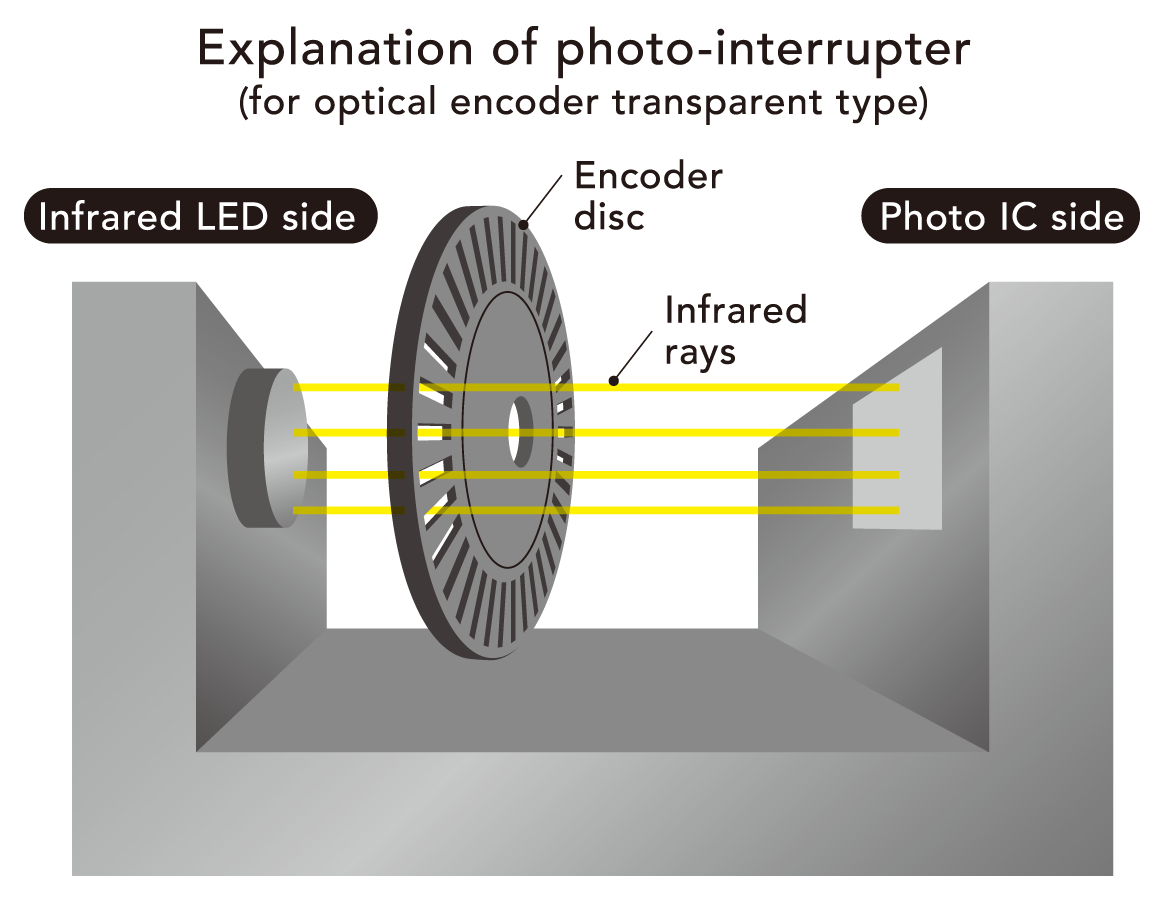

Image Source: https://etching-meltec.com/optical-encoder/

Optical incremental encoders are the most common devices for measuring **angular speed** and **shaft position** in mobile robots.

They consist of:

- A **light source (Useually Infrared LED)**,

- A **rotating disc** with transparent and opaque segments,

- **Optical detectors (Photo IC)**.

As the disc rotates, light passing through the grid generates a **periodic signal **corresponding to angular displacement. The resolution is defined by the number of **cycles per revolution (CPR)**: $Angular \; resolution=\frac{360^\circ }{CPR}$

Typical encoders in mobile robotics range from 2000 to 10,000 CPR. Quadrature encoders, which include two detectors phase-shifted by $90^\circ$, can determine **rotation direction** and **increase resolution by a factor of four**. Thus, a 2000 CPR encoder yields 8000 detectable states per revolution.

**CoppeliaSim Code Example**

**Environment Setup and File Configuration**: This block prepares MATLAB to communicate with CoppeliaSim, locates required files, and ensures everything is ready before starting the simulation. It makes the code portable and avoids path-related errors.

 
clc; clear; close all;

%% 1. CONFIGURATION & SETUP (Dynamic)

% --- Dynamic Path Configuration ---
coppeliaRoot = getenv('COPPELIA_ROOT');

if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

% Build paths
apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

% Add API path
if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene File Setup ---
if matlab.desktop.editor.isEditorAvailable
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    currentScriptPath = pwd;
end

% Construct the scene path
% Target: .../scenes/Wheel_encoder_implementation/encoder scene.ttt
sceneFile = fullfile(currentScriptPath, 'scenes', 'Wheel_encoder_implementation', 'encoder scene.ttt');

% --- Basic Checks ---
if ~isfile(exePath)
    error('CoppeliaSim executable not found: %s', exePath);
end
if ~isfile(sceneFile)
    error('Scene file not found: %s', sceneFile);
else
    disp(['Scene file found: ', sceneFile]);
end

Scene file found: C:\Users\prita\Desktop\Mobile_Robotics-by_AT_IITP\Perception\scenes\Wheel_encoder_implementation\encoder scene.ttt



%% 2. LAUNCH COPPELIASIM
disp('Launching CoppeliaSim...');

Launching CoppeliaSim...


system(['start "" "' exePath '"']);

% Wait for GUI
pause(4); 

% Connect to RemoteAPIClient
timeout = 30; 
tic;
client = [];
disp('Attempting to connect to API...');

while toc < timeout
    try
        client = RemoteAPIClient(); 
        break
    catch
        pause(0.5);
    end
end

if isempty(client)
    error('Could not create RemoteAPIClient. Check ZMQ plugin.');
end

sim = client.getObject('sim');

%% 3. SIMULATION ROUTINE
try
    disp('Loading scene...');
    sim.loadScene(sceneFile);
    pause(1);

    % -----------------------------
    % GET HANDLES
    % -----------------------------
    % Ensure these match your scene hierarchy exactly
    robot      = sim.getObject('/PioneerP3DX');
    leftMotor  = sim.getObject('/PioneerP3DX/leftMotor');
    rightMotor = sim.getObject('/PioneerP3DX/rightMotor');

**Encoder and Robot Parameters**: Defines encoder resolution, robot geometry, and noise model. These parameters directly affect how accurately the robot can estimate its position.

    % -----------------------------
    % PARAMETERS
    % -----------------------------
    ticks_per_revolution = 500;        
    wheel_radius = 0.0975;  % Note: Often radius is ~0.0975m total, or diameter? 
                            % If 0.0975 is diameter, divide by 2. 
                            % Pioneer P3DX wheel radius is usually approx 0.0975m.
    wheel_base   = 0.33;               
    encoder_noise_std = 2;             

   

**Initial State and Encoder Calibration**: Initializes robot pose and ensures encoder readings start correctly. This avoids sudden jumps in position due to incorrect initial assumptions.

 % ODOMETRY STATE INITIALIZATION
    x = 0;          
    y = 0;
    theta = 0;     

    disp('Starting simulation...');
    sim.startSimulation();
    pause(0.5); % Let physics stabilize

    % --- CRITICAL FIX: Initialize previous ticks from ACTUAL start position ---
    % If we assume 0, and the robot starts at 0.1 rad, the first step jumps artificially.
    start_l = sim.getJointPosition(leftMotor);
    start_r = sim.getJointPosition(rightMotor);
    
    prev_left_ticks  = round((start_l / (2*pi)) * ticks_per_revolution);
    prev_right_ticks = round((start_r / (2*pi)) * ticks_per_revolution);

    fprintf("Starting Encoder + Odometry Loop...\n");

**Main Loop: Sensor Reading and Tick Conversion**

Summary: Reads wheel rotation from the simulator and converts it into encoder ticks. This mimics how real robots read wheel encoders.

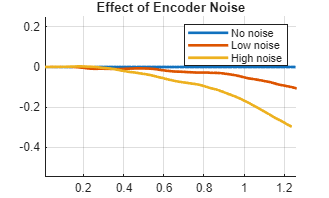

    % -----------------------------
    % MAIN LOOP
    % -----------------------------
    for t = 1:500     
        
        %============================================================

        % 1) READ WHEEL JOINT POSITIONS (radians)
        %============================================================
        left_pos  = sim.getJointPosition(leftMotor);   
        right_pos = sim.getJointPosition(rightMotor);
        
        %============================================================
        % 2) RAD -> TICKS
        %============================================================
        left_ticks  = round((left_pos  / (2*pi)) * ticks_per_revolution);
        right_ticks = round((right_pos / (2*pi)) * ticks_per_revolution);
        

**Noise Injection and Tick Differences:** Adds noise to simulate real encoder errors and computes change in ticks. This step is critical because odometry relies on changes, not absolute values.

        %============================================================
        % 3) ADD ENCODER NOISE (Simulating sensor imperfection)
        %============================================================
        left_ticks_noisy  = left_ticks  + round(encoder_noise_std * randn());
        right_ticks_noisy = right_ticks + round(encoder_noise_std * randn());
        
        %============================================================
        % 4) DELTA TICKS
        %============================================================
        dleft_ticks  = left_ticks_noisy  - prev_left_ticks;
        dright_ticks = right_ticks_noisy - prev_right_ticks;
        
        % Update history for next iteration
        prev_left_ticks  = left_ticks_noisy;
        prev_right_ticks = right_ticks_noisy;
        
        %============================================================
        % 5) TICKS -> ANGLE CHANGE (delta phi)
        %============================================================
        dphi_left  = (dleft_ticks  / ticks_per_revolution) * 2*pi;
        dphi_right = (dright_ticks / ticks_per_revolution) * 2*pi;
        
        %============================================================
        % 6) ANGLE CHANGE -> DISTANCE TRAVELED (wheel arc)
        %============================================================
        dist_left  = dphi_left  * wheel_radius;
        dist_right = dphi_right * wheel_radius;

**Odometry Update (Core Estimation Model)**: Estimates robot position using differential drive kinematics. This is the core of localization based only on wheel motion.

        
        %============================================================
        % 7) ODOMETRY UPDATE (Runge-Kutta / Midpoint approx)
        %============================================================
        d_center = (dist_right + dist_left) / 2;
        d_theta  = (dist_right - dist_left) / wheel_base;
        
        x = x + d_center * cos(theta + d_theta/2);
        y = y + d_center * sin(theta + d_theta/2);
        theta = theta + d_theta;
        
        % Normalize angle to [-pi, pi]
        theta = mod(theta + pi, 2*pi) - pi;
        
        %============================================================
        % 8) LOGGING
        %============================================================
        if mod(t, 20) == 0
            fprintf("Step=%d | x=%.3f | y=%.3f | theta=%.3f rad\n", t, x, y, theta);
        end
        
        % Check if simulation has actually stopped (user pressed stop in GUI)
        if sim.getSimulationState() == sim.simulation_stopped
            disp('Simulation stopped by user.');
            break;
        end
        
        pause(0.05); % Control loop speed
    end

    disp('Simulation loop finished.');
    
    % Stop Simulation
    disp('Stopping simulation...');
    sim.stopSimulation();
    pause(1);
    
    % Quit Simulator
    disp('Quitting simulator...');
    sim.quitSimulator();
    disp('Done.');

catch ME
    % -----------------------------
    % CLEANUP ON ERROR
    % -----------------------------
    warning('An error occurred: %s', ME.message);
    try
        if exist('sim', 'var') && ~isempty(sim)
            sim.stopSimulation();
            sim.quitSimulator();
        end
    catch
        disp('Could not cleanup simulator cleanly.');
    end
    rethrow(ME);
end

## Try Yourself: Encoder Noise vs Drift 

This example shows how **wheel encoder noise affects robot localization**.

In mobile robots, position is often estimated using **odometry**, where wheel rotations are converted into motion. This method assumes that encoder readings are accurate. In practice, however, encoders suffer from **noise and small measurement errors**.

**What the Code Does**

At each step:

- The robot simulates forward motion using encoder ticks 

- Noise is added to the left and right wheel ticks 

- These noisy ticks are converted into: 

- Wheel rotation 

- Linear displacement 

- Change in heading 

- The robot’s position is updated using differential drive kinematics 

This process is repeated for different noise levels.

**Why Noise Causes Drift**

Odometry works by **integrating motion over time**. This means:

- Each small error in measurement is added to the previous state 

- Errors accumulate step by step 

- Even tiny noise leads to large deviation over time 

This is called **drift**.

**What You Observe**

- **No noise** → straight and accurate trajectory 

- **Low noise** → slight deviation from the path 

- **High noise** → large drift and curved or distorted motion 

Even though the robot is commanded to move straight, it gradually moves off track.

**What You Should Try**

- Increase noise further → observe instability 

- Reduce wheel base → see sharper turning errors 

- Add bias (constant offset) → observe systematic drift

noise_levels = [0, 2, 5]; % try different noise

ticks_per_revolution = 500;
wheel_radius = 0.1;
wheel_base = 0.3;

x = 0; y = 0; theta = 0;



figure; hold on

for n = 1:length(noise_levels)
    
    x = 0; y = 0; theta = 0;
    traj = zeros(100,2);
    
    for t = 1:100
        
        % simulate ticks
        dleft = 10 + round(noise_levels(n)*randn());
        dright = 10 + round(noise_levels(n)*randn());
        
        dphi_l = (dleft/ticks_per_revolution)*2*pi;
        dphi_r = (dright/ticks_per_revolution)*2*pi;
        
        dl = dphi_l * wheel_radius;
        dr = dphi_r * wheel_radius;
        
        d_center = (dl+dr)/2;
        d_theta = (dr-dl)/wheel_base;
        
        x = x + d_center*cos(theta);
        y = y + d_center*sin(theta);
        theta = theta + d_theta;
        
        traj(t,:) = [x y];
    end
    
    plot(traj(:,1), traj(:,2),'LineWidth',2)
end

legend('No noise','Low noise','High noise')
axis equal; grid on
title('Effect of Encoder Noise')

## LiDAR

LiDAR (Light Detection and Ranging) is a remote sensing technology that uses laser light to measure distances and create precise, 3D maps of the environment.  The LiDAR sensor emits rapid pulses of laser light (often millions per second) toward a target. The light hits an object (like a wall, a car, or a tree) and bounces back to the sensor. The sensor measures the exact time it took for the light to travel to the object and return.

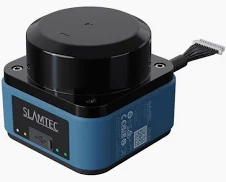

Image source: [https://www.slamtec.com/](https://www.slamtec.com/)

**CoppeliaSim Code Example**

** Environment Setup and Scene Configuration**: This block prepares MATLAB to communicate with CoppeliaSim, builds all required paths, and ensures the LiDAR simulation scene is correctly located. It guarantees that the system is ready before any sensing begins.

 

clc; clear; close all;

%% 1. CONFIGURATION & SETUP (Dynamic)

% --- Dynamic Path Configuration ---
% Get the installation root from the environment variable
coppeliaRoot = getenv('COPPELIA_ROOT');

% Safety check: Ensure the variable exists
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

% Dynamically build the path to the API and Executable
apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

% Add the API path to MATLAB
if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene File Setup ---
if matlab.desktop.editor.isEditorAvailable
    % This grabs the full path of the currently open Live Script
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    % Fallback: use the current working directory if not running from editor
    currentScriptPath = pwd;
end

% Construct the scene path 
% Target: .../scenes/LiDAR_implementation/Lidar_implementation.ttt
sceneFile = fullfile(currentScriptPath, 'scenes', 'LiDAR_implementation', 'Lidar_implementation.ttt');

% --- Basic Checks ---
if ~isfile(exePath)
    error('CoppeliaSim executable not found: %s', exePath);
end
if ~isfile(sceneFile)
    error('Scene file not found at: %s', sceneFile);
else
    disp(['Scene file found: ', sceneFile]);
end


%% 2. LAUNCH COPPELIASIM
disp('Launching CoppeliaSim...');
system(['start "" "' exePath '"']);

% Wait for GUI to open
pause(4); 

% Connect to RemoteAPIClient with timeout
timeout = 30; 
tic;
client = [];
disp('Attempting to connect to API...');

while toc < timeout
    try
        client = RemoteAPIClient(); 
        break
    catch
        pause(0.5);
    end
end

if isempty(client)
    error('Could not create RemoteAPIClient within %d seconds. Check if CoppeliaSim launched correctly.', timeout);
end

sim = client.getObject('sim');


%% 3. SIMULATION ROUTINE
try
    % ------------------------------------------------------------
    % PRE-LOAD CLEANUP
    % ------------------------------------------------------------
    % Ensure any previous simulation is stopped before loading a new scene
    if sim.getSimulationState() ~= sim.simulation_stopped
        disp('Ensuring previous simulation is stopped...');
        sim.stopSimulation();
        while sim.getSimulationState() ~= sim.simulation_stopped
            pause(0.1);
        end
    end

    disp('Loading scene...');
    sim.loadScene(sceneFile);
    pause(1);

    % -------------------------
    % Get object handles
    % -------------------------
    % NOTE: Ensure these names match your scene hierarchy exactly
    % The generic 'laser' might need to be specific if you have multiple sensors
    lidarHandle = sim.getObject('/LiDAR/laser'); 
    lidarJoint  = sim.getObject('/LiDAR/joint');
    leftMotor   = sim.getObject('/PioneerP3DX/leftMotor');
    rightMotor  = sim.getObject('/PioneerP3DX/rightMotor');

**LiDAR Parameters and Scan Setup**: Defines how the LiDAR scans the environment. It sets scan angle, number of points, and maximum detection range, which together determine resolution and coverage.

    % -------------------------
    % LiDAR parameters
    % -------------------------
    scanningAngle = 2 * pi;       
    pts           = 684;          
    maxScanDist   = 6;            
    
    % Pre-allocate arrays for plotting
    angles = linspace(-scanningAngle/2, scanningAngle/2, pts);
    ranges = maxScanDist * ones(1, pts);

    % -------------------------
    % Create Live Figure 
    % -------------------------
    hFig = figure('Name','LiDAR Scan (Live)', 'NumberTitle', 'off');
    hPlot = polarplot(angles, ranges, '.b', 'MarkerSize', 5);
    rlim([0 maxScanDist]);
    title('Initializing LiDAR...');
    grid on;
    
    % -------------------------
    % Start Simulation
    % -------------------------
    disp('Starting simulation...');
    
    % We do NOT use stepping mode here unless strictly necessary for synchronization
    % because it can slow down visualization significantly.
    % However, if you need frame-perfect sensor data, keep stepping enabled.
    % sim.setStepping(true); 
    
    sim.startSimulation();
    
    % Move robot forward to see changing scan
    sim.setJointTargetVelocity(leftMotor, 1);
    sim.setJointTargetVelocity(rightMotor, 1);

    % -------------------------------------------------
    % DATA SAMPLING LOOP
    % -------------------------------------------------
    num_scans = 50; % Increased iterations so you can actually see it move
    fprintf('Collecting %d scans...\n', num_scans);
    
   

**LiDAR Scanning Loop (Core Perception Logic)**: This is the core sensing process. The LiDAR rotates, sends beams, detects obstacles, and records distances. This simulates how real LiDAR sensors build a scan.

 for scan_idx = 1:num_scans
        
        % In a real sensor, you get the whole scan at once. 
        % In this specific simulation model, we might need to iterate 
        % if it's a rotating single-beam sensor simulation.
        
        current_ranges = zeros(1, pts);
        
        % Rotating the sensor programmatically (if your scene requires it)
        % Note: Usually modern Lidar sensors in Coppelia handle rotation internally.
        % If your script manually rotates the joint, we loop through points:
        for i = 1:pts
            % Set joint angle for the single beam
            sim.setJointPosition(lidarJoint, angles(i));
            
            % Read sensor
            [res, dist] = sim.readProximitySensor(lidarHandle);
            
            if res > 0
                current_ranges(i) = dist;
            else
                current_ranges(i) = maxScanDist; % No echo = max range
            end
            
            % If using stepping mode, advance physics one tick per beam
            % sim.step(); 
        end
        
        % Update Plot with the full scan data
        if ishandle(hPlot)
            set(hPlot, 'RData', current_ranges);
            title(sprintf('LiDAR Scan: %d / %d', scan_idx, num_scans));
            drawnow limitrate;
        else
            break; % Figure closed
        end
        
        % Check if user stopped sim in GUI
        if sim.getSimulationState() == sim.simulation_stopped
            break;
        end
    end

    % -------------------------
    % STOP & CLEANUP
    % -------------------------
    disp('Stopping simulation...');
    sim.stopSimulation();
    pause(1);
    
    disp('Quitting simulator...');
    sim.quitSimulator();
    disp('Done.');
    
    if ishandle(hFig)
        title('Simulation Complete (Final Scan)');
    end

catch ME
    % -------------------------
    % ERROR HANDLING
    % -------------------------
    warning('An error occurred: %s', ME.message);
    try
        if exist('sim', 'var') && ~isempty(sim)
            sim.stopSimulation();
            sim.quitSimulator();
        end
    catch
        % ignore cleanup errors
    end
    rethrow(ME);
end

## Compasses

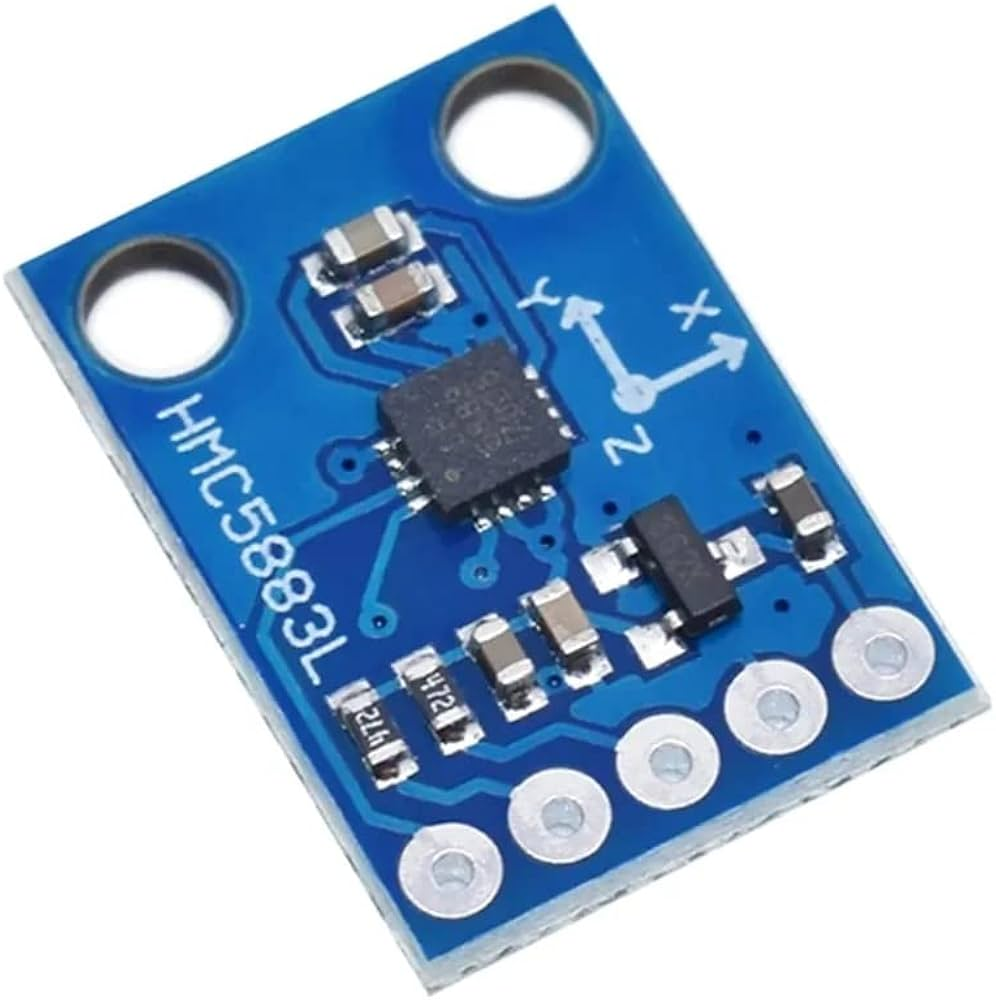

Image source: Robodo GY273 HMC5883L

A mobile robot's compass sensor, determines its absolute heading direction with respect to a reference direction. Two main principles are used:

- **Hall-effect compasses** — measure voltage induced by magnetic fields in a semiconductor. Two orthogonal sensors provide magnetic direction. They are inexpensive but suffer from low resolution, slow response (~2.5 s to settle for a 90° turn), and high susceptibility to interference from ferrous materials.

- **Flux-gate compasses** — employ ferrite-core coils excited by alternating current. The phase shift between the coils encodes field direction. They provide higher accuracy and resolution but are bulkier and costlier.

Note that magnetic compasses are unreliable in indoor environments due to distortion from building materials and electromagnetic noise.

## Gyroscopes

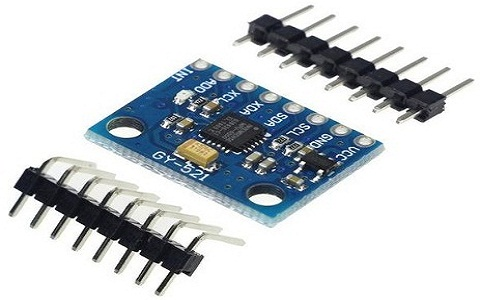

Image source: www.watelectronics.com

A gyroscope sensor measures the orientation and angular velocity of a mobile robot. 

**Mechanical gyroscopes:**

Contain a rapidly spinning rotor suspended on gimbals. Due to **gyroscopic precession**, the rotor resists external torque, maintaining inertial stability: $\tau =I\omega \Omega $, where $I = \text{ moment of inertia,} \:


\omega  =  \text{spin speed,} \:


\Omega  =  \text{precession rate}$.

**Optical gyroscopes:**

Optical gyroscope use two counter-propagating laser beams in a coiled fiber to measure angular velocity via the **Sagnac effect.**

## Accelerometers

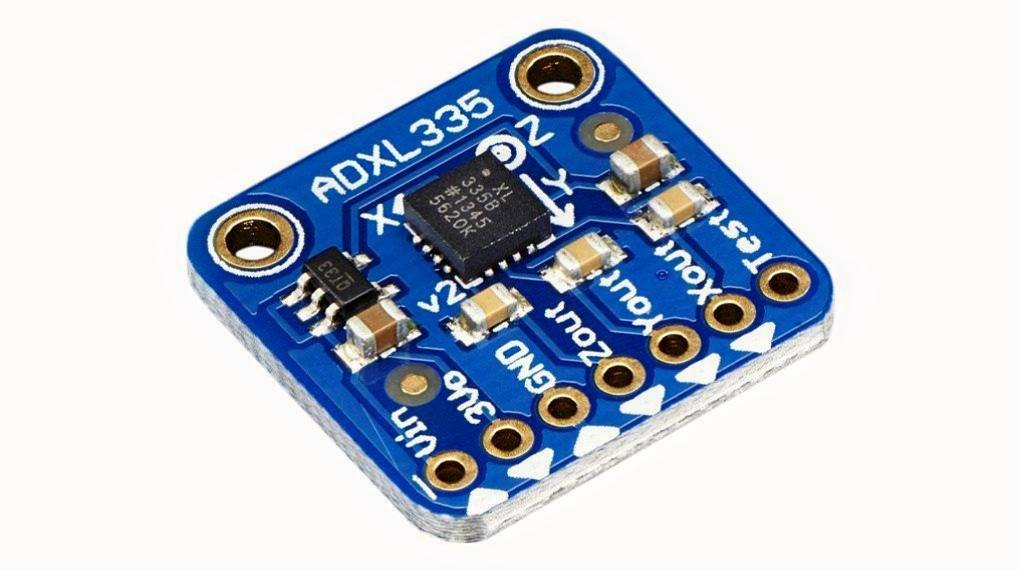

Image source: [https://robu.in/](https://robu.in/) (Triple Axis Accelerometer) 

Accelerometers in mobile robots measure linear motion, changes in velocity, and gravity, which allows them to determine orientation, detect impacts, and assist in positioning through dead reckoning. Modern accelerometers are **MEMS (Micro Electro-Mechanical Systems)** devices that measure deflection capacitively or piezoelectrically. 

## Inertial Measurement Unit (IMU)

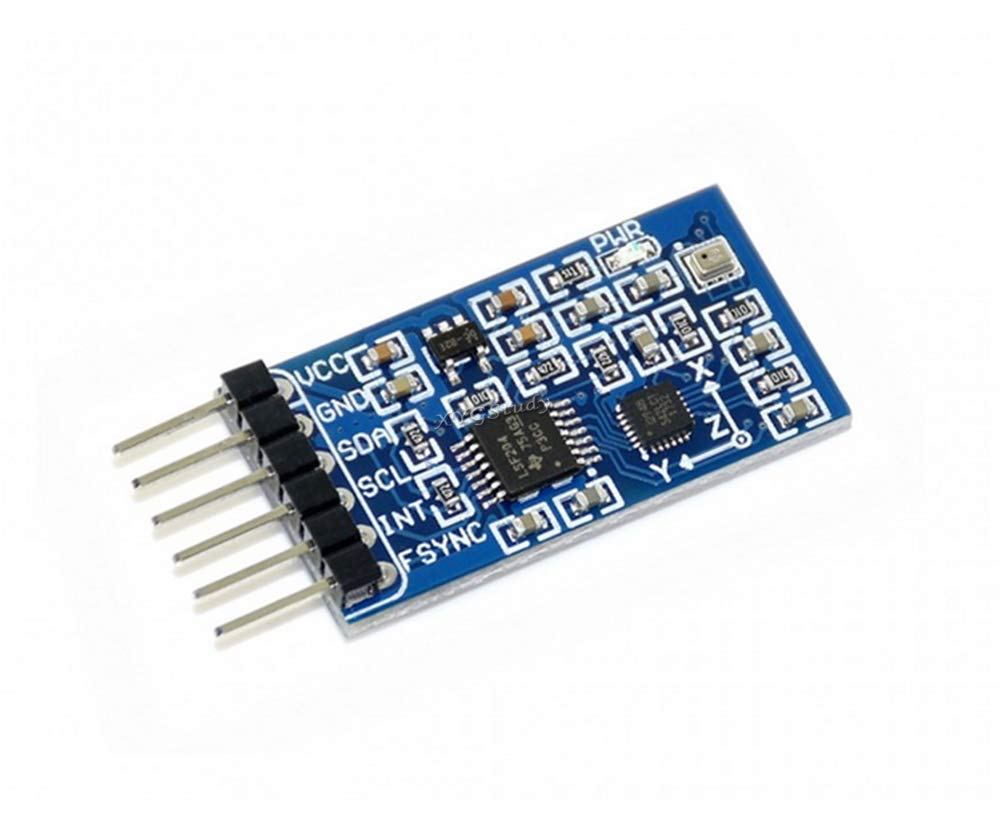

An **Inertial Measurement Unit (IMU)** combines accelerometers and gyroscopes to estimate a vehicle’s **6-DOF pose, **position $(x,y,z)$ and orientation (roll, pitch, yaw). The IMU integrates gyroscope data to compute orientation, and then transforms acceleration readings into the navigation frame. 

**CoppeliaSim Code Example**

**Environment Setup and Scene Configuration**: This block prepares MATLAB to communicate with CoppeliaSim and ensures the IMU simulation scene is correctly located. It builds all required paths and verifies that the simulator and scene are available.

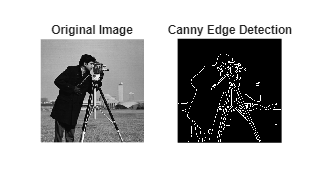

 
clc; clear; close all;

%% 1. CONFIGURATION & SETUP (Dynamic)

% --- Dynamic Path Configuration ---
% Get the installation root from the environment variable
coppeliaRoot = getenv('COPPELIA_ROOT');

% Safety check: Ensure the variable exists
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');

end

% Dynamically build the path to the API and Executable
apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

% Add the API path to MATLAB
if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene File Setup ---
if matlab.desktop.editor.isEditorAvailable
    % This grabs the full path of the currently open Live Script
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    % Fallback: use the current working directory if not running from editor
    currentScriptPath = pwd;
end

% Construct the scene path 
% Target: .../scenes/IMU_implementation/imu scene.ttt
sceneFile = fullfile(currentScriptPath, 'scenes', 'IMU_implementation', 'imu scene.ttt');

% --- Basic Checks ---
if ~isfile(exePath)
    error('CoppeliaSim executable not found: %s', exePath);
end

if ~isfile(sceneFile)
    warning('Scene file not found at: %s', sceneFile);
    disp('Please check that the folder "IMU_implementation" and file "imu scene.ttt" exist.');
else
    disp(['Scene file found: ', sceneFile]);
end


%% 2. LAUNCH COPPELIASIM
disp('Launching CoppeliaSim...');
system(['start "" "' exePath '"']);

% Wait for GUI to open
pause(4); 

% Connect to RemoteAPIClient with timeout
timeout = 30; 
tic;
client = [];
disp('Attempting to connect to API...');

while toc < timeout
    try
        client = RemoteAPIClient(); 
        break
    catch
        pause(0.5);
    end
end

if isempty(client)
    error('Could not create RemoteAPIClient within %d seconds. Check if CoppeliaSim launched correctly.', timeout);
end

sim = client.getObject('sim');


%% 3. SIMULATION ROUTINE
try
    disp('Loading scene...');
    % Only load if the file actually exists to avoid crashing empty sim
    if isfile(sceneFile)
        sim.loadScene(sceneFile);
    end
    pause(1);

    % -------------------------
    % Get handles
    % -------------------------
    % Ensure these names match your Scene Hierarchy exactly
    % If using the generic generic Pioneer model, these are standard:
    imuHandle  = sim.getObject('/IMU');
    leftMotor  = sim.getObject('/PioneerP3DX/leftMotor');
    rightMotor = sim.getObject('/PioneerP3DX/rightMotor');

    % -------------------------
    % Simulation Parameters
    % -------------------------
    dt = 0.05;           % Time step for data collection
    prevVel = [0 0 0];   % Initialization for acceleration calc

    disp('Starting Simulation & Moving Robot...');
    

**Start Simulation and Robot Motion**: Starts the simulation and moves the robot so that the IMU experiences motion. Without motion, IMU readings would be trivial.

sim.startSimulation();
    
    % Set robot moving so we get some IMU readings
    sim.setJointTargetVelocity(leftMotor,  2);
    sim.setJointTargetVelocity(rightMotor, 2);
 

**IMU Data Acquisition Loop (Core Sensing)**: Continuously reads velocity, angular velocity, and orientation from the IMU. These are the three main outputs of an inertial measurement unit.

   
    disp('Reading IMU Data...');
    fprintf('---------------------------------------------\n');

    % -------------------------------------------------
    % IMU DATA LOOP
    % -------------------------------------------------
    for i = 1:200
        
        % 1. Get Raw Data from Simulator
        % Note: The ZMQ API often returns these as Cell Arrays (e.g., {0.1, 0.2, 0.3})
        [linearVel, angularVel] = sim.getObjectVelocity(imuHandle);
        euler = sim.getObjectOrientation(imuHandle, -1);
        
        % 2. Data Conversion (Cell -> Matrix)
        % We check if they are cells and convert them to standard MATLAB vectors [x, y, z]
        if iscell(linearVel)
            linearVel = [linearVel{:}]; 
        end
        if iscell(angularVel)
            angularVel = [angularVel{:}];
        end
        if iscell(euler)
            euler = [euler{:}];
        end
        
        % Safety check: If simulation stopped unexpectedly, data might be empty
        if isempty(linearVel) || isempty(angularVel)
            continue;
        end

        % 3. Calculate Acceleration (Simple discrete derivative)
        % Accel = (V_current - V_prev) / dt
        accel = (linearVel - prevVel) / dt;
        
        % Update previous velocity for next iteration
        prevVel = linearVel;
        
        % Gyro data is just the angular velocity
        omega = angularVel;

        % 4. Print Data (Formatted)
        % Print every 10th sample to avoid flooding the command window
        if mod(i, 10) == 0
            fprintf('Sample %d\n', i);
            fprintf('  Accel [m/s^2] : X = %5.2f | Y = %5.2f | Z = %5.2f\n', accel(1), accel(2), accel(3));
            fprintf('  Gyro  [rad/s] : X = %5.2f | Y = %5.2f | Z = %5.2f\n', omega(1), omega(2), omega(3));
            fprintf('  Euler [rad]   : R = %5.2f | P = %5.2f | Y = %5.2f\n', euler(1), euler(2), euler(3));
            fprintf('---------------------------------------------\n');
        end
        
        % Pause to sync with the loop speed (approximate real-time)
        pause(dt);
        
        % Check if user stopped simulation manually
        if sim.getSimulationState() == sim.simulation_stopped
            break;
        end
    end

    % -------------------------
    % STOP & CLEANUP
    % -------------------------
    disp('Stopping simulation...');
    sim.stopSimulation();
    pause(1);
    
    disp('Quitting simulator...');
    sim.quitSimulator();
    disp('Done.');

catch ME
    % -----------------------------
    % CLEANUP ON ERROR
    % -----------------------------
    warning('An error occurred: %s', ME.message);
    try
        if exist('sim', 'var') && ~isempty(sim)
            sim.stopSimulation();
            sim.quitSimulator();
        end
    catch
        % ignore cleanup errors
    end
    rethrow(ME);
end

## Global Positioning System (GPS)

GPS uses at least **four satellites** to triangulate 3D position and time synchronization to provide **absolute position estimates of an object** by measuring the time delay between transmitted and received radio signals from satellites. Each satellite transmits its position and timestamp; the receiver measures **time of flight** differences to compute its location. Each satellite transmits:

- Its precise **position** $(x
_i
,y
_i
,z
_i
),$

- A **timestamp** indicating the signal’s transmission time.

The GPS receiver measures the **time of arrival (**$t_r$**)** of each signal, and thus the pseudorange $d
_i$ for the $i^{th}$ satellite is given by $d^i=c(t_r-t^i)=r^i+ct_b$, which represents the distance between the satellite and receiver **plus** an additional clock bias term $ct_b$, where $c$ = speed of light (m/s), $t_b$ = receiver clock bias (s) and $r^i  = \sqrt{(xi-x)^2+(yi-y)^2+(zi-z)^2}$. 

The relationship for each satellite $i$ is expressed as: $[(x^1-x)^2+(y^1-y)^2+(z^1-z)^2]^{0.5} = d^1+ct_b
\\
[(x^2-x)^2+(y^2-y)^2+(z^2-z)^2]^{0.5} =d^2+ct_b
\\
[(x^3-x)^2+(y^3-y)^2+(z^3-z)2]^{0.5} =d^3+ct_b
\\
[(x^4-x)^2+(y^4-y)^2+(z^4-z)^2]^{0.5} = d^4+ct_b\\

$

Here, $(x,y,z)$ is the unknown receiver position.

## Active Ranging Sensors

Active ranging sensors emit energy and measure its reflection to compute distance. They are widely used for **obstacle detection** and **environment modeling**.

**Ultrasonic Sensors:** Emit high-frequency sound (40–180 kHz) and measure echo time: $d=\frac{ct}{2}$. They are inexpensive but have wide beam angles (20–40°) and suffer from **specular reflections** and **slow refresh rates** (2–50 Hz). 

**Laser Rangefinders (LiDAR):** Use laser pulses or continuous modulated beams to measure distance via **phase shift**: $D= \frac{\lambda \phi }{4\pi }$ , where $D $ is the measured distance from LiDAR sensor to target, $\lambda $is the wavelength of the modulated carrier wave, and $\phi $ is the measured **phase shift** between transmitted and received wave. They offer millimeter level accuracy and high angular resolution. 3D LiDAR systems achieve sub-2 cm accuracy and > 1 M points/sec, enabling 3D mapping. 

# **Vision Sensors**

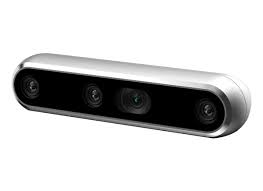

Image source: https://www.mouser.in

Light from one or more sources reflects from surfaces, passes through optics and an aperture, and finally arrives at an image sensor. On the sensor each photon can liberate an electron, electrons accumulate in photosensitive elements (pixels) during an exposure interval (the integration time). After exposure the accumulated charges are read out, amplified, converted to voltages and then digitized by an analog-to-digital converter (ADC). The result is a 2D array of digital samples.

A camera system therefore consists of optics, an aperture, a photodetector array (CCD or CMOS), per-pixel or per-column electronics (gain, ADC), and firmware/software that forms output frames in some format (RAW, USB/FW transport, or compressed video).                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

## Sensor technologies: CCD (Charge-Coupled Device) vs CMOS (Complementary Metal-Oxide-Semiconductor)

**CCD:** CCD is an array of photodiodes whose charges are **shifted** across the chip to a single (or a few) output amplifiers. Each pixel behaves like a small well (capacitor) that collects electrons during integration. After exposure the charge packets are clocked row by row to a readout node where they are measured. They provide excellent pixel uniformity, low fixed-pattern noise, and very good image quality for a given process generation. But they require complex clocking and specialized fabrication, relatively high power and limited flexibility.

**CMOS:** Each pixel typically includes one or more transistors, so pixel voltages can be read locally. Readout is performed in parallel along columns/rows using standard CMOS peripheral circuits. They are suitable and inexpensive for mass fabrication, low power consumption, fast random access, on-chip amplification/processing, and low cost.

## Camera control parameters 

**1. Aperture (Iris)**

- **Parameter:** $f$-number (e.g., $f/1\ldotp 8,f/8\ldotp 0$)

- **Function:** Controls the diameter of the lens opening.

- **Primary Effect:** Regulates the **amount of light** reaching the sensor. A lower $f$-number means a larger opening, letting in more light.

- **Large Aperture (low **$f$**-number):** Creates a **shallow Depth of Field (DoF)**. Only a narrow plane in the scene is in focus, which is often *undesirable* for robotics, as you might miss obstacles or landmarks.

- **Small Aperture (high **$f$**-number):** Creates a **deep DoF**, keeping more of the scene (both near and far objects) in sharp focus. This is generally *preferred* for situational awareness.

**2. Shutter Speed (Exposure Time)**

- **Parameter:** Measured in seconds $(e.g., 1/1000\text{s}, 1/30\text{s})$

- **Function:** Defines the "integration period"—the duration the sensor is actively collecting photons.

- **Primary Effect:** Controls the total light captured and motion blur.

- **Short Exposure (fast shutter):** "Freezes" motion, resulting in a crisp image with minimal **motion blur**. This is critical for high-speed robot navigation or tracking fast-moving objects. The drawback is that it requires more ambient light or higher gain.

- **Long Exposure (slow shutter):** Collects more light, which is good for dark environments. However, it causes significant **motion blur** (from both robot and object movement) and can increase sensor noise (like **dark current**).

**3. Gain (ISO)**

- **Parameter:** Analog or digital amplification factor (e.g., 100 ISO, 3200 ISO)

- **Function:** Applies electronic amplification to the analog signal *before* the Analog-to-Digital Converter (ADC).

- **Primary Effect:** Brightens the image.

- **Crucial Caveat:** As you correctly noted, **gain does not add new information** or increase the photons captured. It merely scales the existing signal. For vision tasks, it's always best to get more light via aperture or shutter speed first, using gain only as a last resort to achieve the desired Signal-to-Noise Ratio (SNR).

**4. White Balance (WB)**

- **Parameter:** Per-channel (R, G, B) gains.

- **Function:** Compensates for the spectral distribution (i.e., "color temperature") of the ambient light, ensuring that white objects appear neutral white.

- **Implication for Vision:** For tasks like color-based segmentation or object recognition, **Auto White Balance (AWB) can be harmful.** AWB can cause the apparent color of an object to change from frame to frame as the lighting or scene composition changes. It is highly recommended to **use a fixed (manual) white balance** setting, calibrated for the operational environment.

**5. Frame Rate (fps) & Readout Mode**

- **Parameter:** Frames per second (e.g., 30 fps, 60 fps)

- **Function:** The rate at which full images are read from the sensor.

- Frame rate sets the **maximum possible exposure time**. At 30 fps, your exposure time must be $$\leq 1/30\text{s}$$.

- The **Readout Mode** is critical. **Rolling Shutter** (common in CMOS sensors) reads the sensor line by line, which can cause significant **skew and "jello" artifacts** when the robot is moving or rotating quickly. For robotics, a **Global Shutter** (which reads the entire sensor at once) is vastly superior as it provides a true, artifact-free snapshot of the scene at a single point in time.

## Color Cameras

The basic light-measuring process is fundamentally **achromatic **where each pixel on an image sensor simply measures the **total number of photons** that strike it during the exposure period, regardless of wavelength. To capture color information, the camera must discriminate light by its **spectral content**, typically dividing it into three broad wavelength bands corresponding to **red (R), green (G), and blue (B)**. Two principal hardware strategies exist for this purpose: **single-chip color sensors** and **three-chip color sensors**.

**Single-chip color cameras (Bayer filter sensors): **Most digital and robotic cameras today use a single imaging chip covered by a color filter array (CFA). In this design, the sensor’s pixels are arranged in repeating 2×2 cells, where each pixel is covered by a microscopic red, green, or blue filter that allows only light of that color to reach the underlying photodiode. Each cell contains two green, one red, and one blue pixel. This uneven distribution mirrors the human visual system, which is far more sensitive to luminance (brightness) variations dominated by green light than to chrominance (color) differences. Consequently, green samples are doubled to improve the perceived sharpness of the reconstructed image. However, because each pixel measures only a single color component, the missing two color channels must be estimated algorithmically. This reconstruction process is known as demosaicing (or color interpolation). Sophisticated demosaicing algorithms ranging from simple bilinear interpolation to edge-adaptive and gradient-based methods reconstruct full RGB values for every pixel.

A trade-off of this single-chip approach is effective spatial resolution: although the sensor may contain N physical pixels, only about one-third directly measure each color component. Thus, the geometric resolution of the color image is somewhat reduced relative to a monochrome sensor of the same size. The practical loss depends on both the CFA pattern and the demosaicing method.

**Three-chip color cameras:** Three-chip color cameras eliminate the need for a color filter array. Instead, a beam-splitting prism assembly divides the incoming light into three separate optical paths, typically using dichroic coatings that reflect or transmit specific wavelength bands. Each path directs light onto a dedicated monochrome sensor, one for red, one for green, and one for blue. This configuration allows each sensor to measure full-resolution intensity data for its respective spectral band. The three resulting images are then electronically combined to produce a high-fidelity color image with no demosaicing artifacts and full spatial resolution. The advantages are excellent color accuracy, superior low-light performance, and higher dynamic range, since no light is lost to CFA filters. However, these benefits come at the cost of greater optical complexity, bulkier design, and significantly higher price, making three-chip cameras rare in mobile robotic platforms where cost, weight, and power consumption are constrained.

Regardless of architecture, both single-chip and three-chip cameras share a common physical limitation. Silicon photodiodes are not equally sensitive across the visible spectrum. Their spectral response extends roughly from 400 nm to 1000 nm, peaking in the red (near-infrared) region. As a result, blue light (short wavelengths) produces fewer electrons, reducing signal strength. Infrared light (long wavelengths) may be overrepresented, since the photodiodes remain sensitive beyond the visible range. To suppress unwanted infrared contamination, most color cameras incorporate an IR-cut filter in front of the sensor. Even so, blue-channel amplification (gain) is typically required to balance the overall color response. This necessary gain increase also amplifies electronic noise, making the blue channel inherently noisier, often by one to two effective bits, than red or green. Although advances such as backside illumination and improved microlenses have enhanced blue sensitivity, this spectral imbalance remains an important consideration for quantitative vision systems.

Color cameras must also account for the spectral characteristics of illumination. Light sources such as sunlight, fluorescent lamps, and incandescent bulbs have markedly different spectral power distributions, meaning that the combination of red, green, and blue that constitutes “white” light changes with the source. Human vision naturally performs color constancy, perceiving white surfaces as neutral under varying lighting conditions. Digital cameras, however, do not possess such innate adaptability. Without correction, the same object may appear bluish under daylight and yellowish under tungsten illumination. To address this, cameras employ white balance control, which adjusts the relative amplification (gain) of the red, green, and blue channels so that a reference white surface appears neutral.

## Image formation

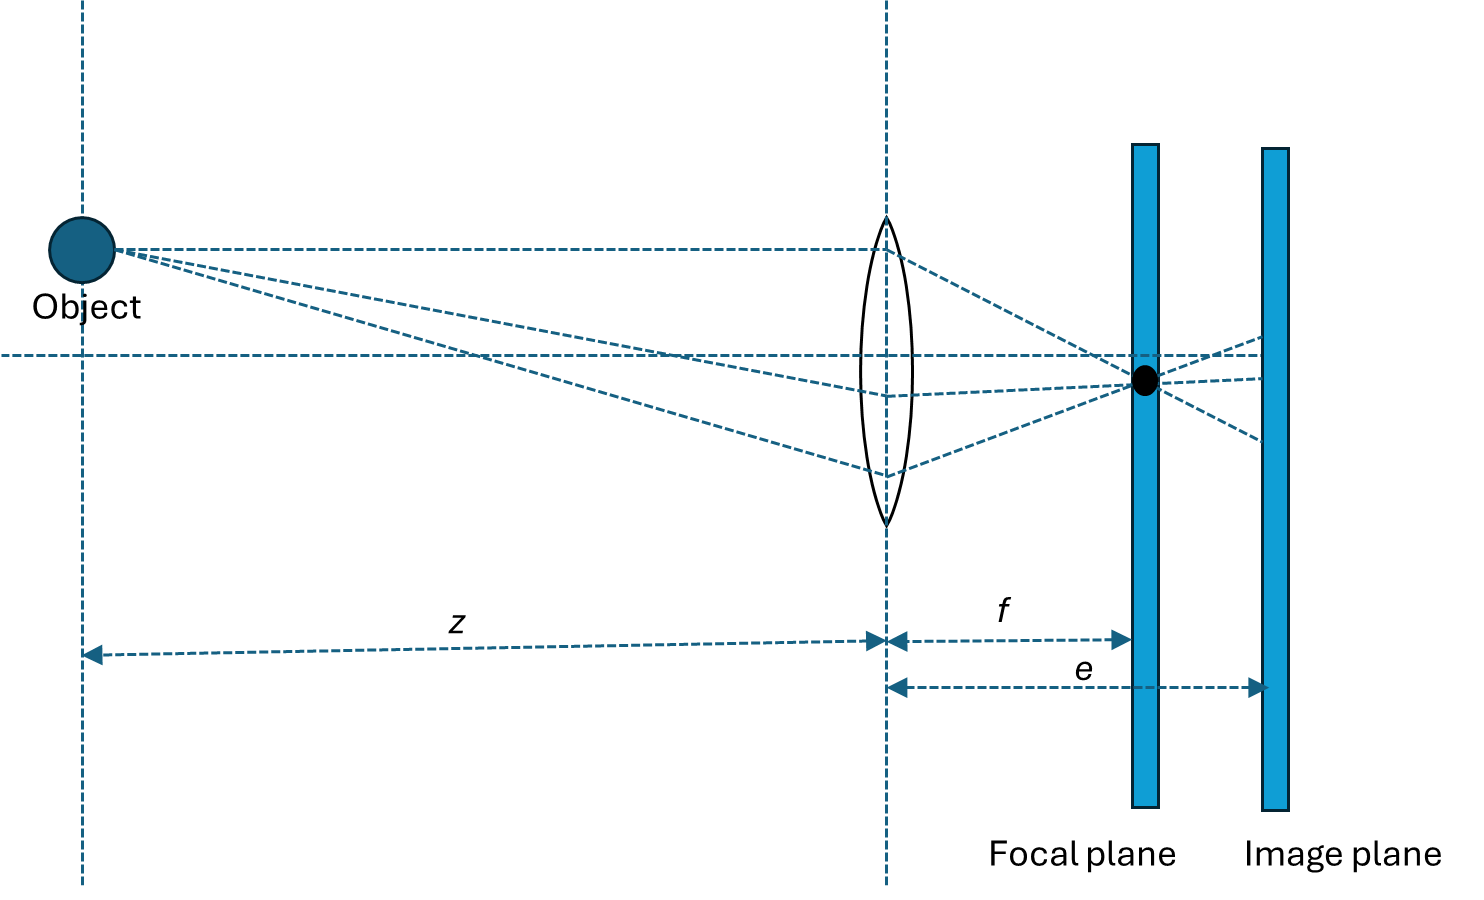

**Fig. 1: Depiction of camera optics**

To analyze and process images reliably, we must first understand how those images were formed. Image formation describes the chain of physical and geometric events that transform radiance in the scene into digital samples on a sensor: illumination → reflection → optics → sensor integration → readout → digitization. 

A convenient, widely used model for camera optics is the thin lens. For an object at distance $z$ (measured from the lens) and an image formed at distance $e$ behind the lens, the thin-lens equation is given by $\frac{1}{z}+\frac{1}{e}=\frac{1}{f}$, where $f$ is the focal length of the lens. This relation links the physical distance of scene points to the position of their sharp image on the image plane; consequently, by measuring the position of the image plane that produces maximum sharpness one can infer range. If the image plane is placed exactly at $e$ for a given object, light from that object is focused to a single point. If the image plane is displaced from that conjugate position, the object projects as a *blur circle* (the *circle of confusion*). The radius $R$ of this blur circle scales with the lens aperture size and with the image-plane displacement $\delta$ (the distance between the actual image plane and the in-focus plane): $R\propto\frac{|L|}{2e}$ , where $L$ is the aperture diameter and $e$ is the image-plane distance. Thus, larger apertures produce larger blur for the same amount of defocus; conversely, closing the iris (reducing $L$) reduces blur and increases the **depth of field.**

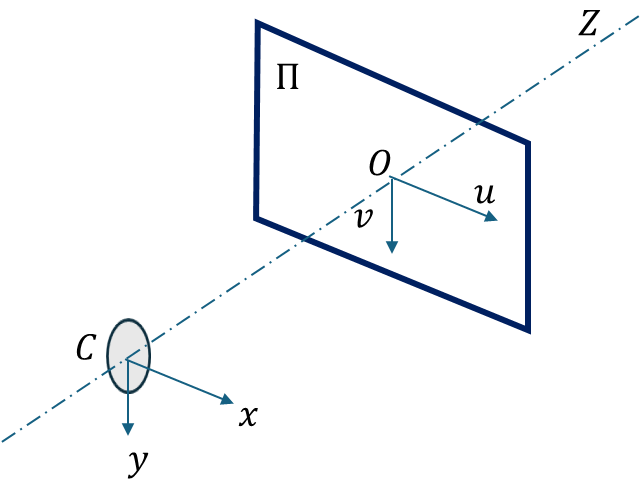

**Fig. 2: Pinhole camera model**

**Pinhole Camera Model: **Geometrically, the pinhole camera establishes a **one-to-one mapping** between rays in 3D space and points on the image plane. Each scene point emits or reflects light in many directions, but only the ray passing through the pinhole contributes to its projection. If the distance between the pinhole and the image plane is denoted by $f$, the same geometry as a thin lens focused at infinity applies, satisfying the relation $e=f$ for $z\to \infty $. Hence, a lens with focal length $f$ can be approximated by a pinhole camera located at distance $f$ from the image plane. This equivalence makes the pinhole camera model a natural **mathematical abstraction** for perspective projection. Refer to Fig. 2, the **center of projection (C)** corresponds to the pinhole itself and represents the single point through which all rays pass. The **optical axis** is the line perpendicular to the image plane that passes through this center. The **principal point (O)** is the intersection of the optical axis with the image plane, serving as the reference for image coordinates. For convenience in geometric analysis, the model is often represented with the image plane placed **in front of** the center of projection so that the projected image appears upright rather than inverted. The **center of projection (C)** corresponds to the pinhole itself and represents the single point through which all rays pass. The **optical axis** is the line perpendicular to the image plane that passes through this center. The **principal point (O)** is the intersection of the optical axis with the image plane, serving as the reference for image coordinates. For convenience in geometric analysis, the model is often represented with the image plane placed **in front of** the center of projection so that the projected image appears upright rather than inverted.

**Perspective Projection: **Perspective projection model describes the geometric transformation between a scene point in 3D space and its image on the camera’s sensor plane. Let the camera reference frame be defined by coordinates $(x,y,z)$, with its origin at the optical center $C$and the **z-axis aligned with the optical axis **(see Fig. 2). The image plane $\Pi $ is positioned at a distance $f$ (the focal length) in front of the pinhole, and a 2D coordinate system $(u,v)$ is defined on this plane with its origin $O$ at the principal point (the intersection of the optical axis with the image plane). For a 3D point $P=(x,y,z)$ in the camera coordinate frame, its projection $
p=(u,v)$ on the image plane can be derived using simple geometric similarity of triangles $u=f\frac{x}{z},v=f\frac{y}{z}$. This relation is known as the **perspective projection equation**. It expresses how image coordinates vary nonlinearly with the depth $z$. Points farther away (larger $z$) project closer to the principal point, illustrating the fundamental property of perspective: objects appear smaller as they recede from the camera. Because of the division by $z$, this mapping is nonlinear in Cartesian coordinates. However, by introducing **homogeneous coordinates**, the relationship becomes linear: $\tilde{p} = \pmatrix{\lambda u \cr \lambda v \cr \lambda} = \pmatrix{f \; 0 \; 0\; 0 \cr 0\; f \; 0\; 0 \cr  0 \; 0 \; 1\; 0}  \pmatrix{x \cr y \cr z \cr 1}$ . This matrix form represents the **ideal pinhole projection model**.

**Radial Distortion:** The ideal perspective projection model assumes a **linear relationship** between points in the 3D world and their projections on the image plane, meaning that **straight lines in the world should appear straight in the image**. In practice, however, this assumption breaks down due to imperfections in real lenses. The most significant of these effects is **radial distortion**, a nonlinear displacement of image points that becomes particularly pronounced in **wide-angle or short focal-length lenses**, where the field of view is large. Radial distortion causes image points to be displaced **along radial directions** from the optical center (the principal point). The amount of displacement increases with the **distance **$r$ from the image center, where $r= \sqrt{(u-u_0)^2+(v-v_0)^2}
,$ and $(u_0,v_0)$ denote the principal point coordinates. 

Depending on the sign of the distortion, two primary types are observed:

- **Barrel distortion:** points are displaced **away** from the image center, causing straight lines to bulge outward.

- **Pincushion distortion:** points are displaced **toward** the image center, making straight lines appear to bend inward.

**Camera Calibration:** **Camera calibration** is the process of accurately determining a camera’s **intrinsic** and **extrinsic** parameters.

**Classical Calibration Methods**

**Classical Calibration** method uses a **two-stage approach**:

- **Extrinsic parameter estimation:** determine the camera’s position and orientation relative to a known 3D calibration target.

- **Intrinsic parameter estimation:** compute the internal parameters of the camera, including focal length, principal point, and distortion coefficients.

The method requires a calibration object with **known 3D coordinates** and a set of corresponding **2D image points**. Although precise, this approach demands accurate 3D measurement of the target points, making it somewhat cumbersome for non-laboratory environments.

**Planar Grid Calibration**

This method relies on a **planar grid pattern**, most commonly a **checkerboard**, whose geometry is known precisely. This makes the method simple, robust, and easy to use even for non-experts.

The procedure is as follows:

- Print or display a planar checkerboard grid with known square size.

- Capture **multiple images** of the pattern at **different positions and orientations** within the camera’s field of view.

- Detect the **corner points** of the checkerboard in each image.(Modern toolboxes use subpixel corner detection for high accuracy.)

- For each image, estimate a **homography** (the planar projective transformation) that relates the known 2D grid coordinates to the image coordinates.

- Solve a **least-squares problem** to recover the intrinsic parameters.

- Refine all parameters simultaneously using a **nonlinear optimization** (e.g., Gauss–Newton or Levenberg–Marquardt) to minimize the **reprojection error**, i.e., the pixel distance between observed and predicted corner locations.

The method naturally incorporates **radial and tangential distortion** terms, allowing complete modeling of standard perspective cameras.

**Toolboxes and Implementation**

The above methods have been implemented in several widely used calibration toolkits:

- The **Camera Calibration Toolbox for MATLAB**, developed by **Jean-Yves Bouguet**, provides an intuitive interface for capturing checkerboard images, extracting corners, estimating parameters, and visualizing results.

- The same algorithm is implemented in **OpenCV**, an open-source computer vision library in C/C++, with Python and MATLAB bindings for broader accessibility.

**CoppeliaSim Code Example**

**Environment Setup and Scene Configuration**: This block prepares MATLAB to communicate with CoppeliaSim, builds all required paths, and ensures the camera simulation scene is available. It sets up the system for visual sensing.

 
clc; clear; close all;

%% 1. CONFIGURATION & SETUP (Dynamic)

% --- Dynamic Path Configuration ---
% Get the installation root from the environment variable
coppeliaRoot = getenv('COPPELIA_ROOT');

% Safety check: Ensure the variable exists
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

% Dynamically build the path to the API and Executable
apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

% Add the API path to MATLAB
if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene File Setup ---
if matlab.desktop.editor.isEditorAvailable
    % This grabs the full path of the currently open Live Script
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    % Fallback: use the current working directory if not running from editor
    currentScriptPath = pwd;
end

% Construct the scene path 
% Target: .../scenes/camera implementation/camera_rgb scene.ttt
sceneFile = fullfile(currentScriptPath, 'scenes', 'camera implementation', 'camera_rgb scene.ttt');

% --- Basic Checks ---
if ~isfile(exePath)
    error('CoppeliaSim executable not found: %s', exePath);
end
if ~isfile(sceneFile)
    warning('Scene file not found at: %s', sceneFile);
else
    disp(['Scene file found: ', sceneFile]);
end


%% 2. LAUNCH COPPELIASIM
disp('Launching CoppeliaSim...');
system(['start "" "' exePath '"']);

% Wait for GUI to open
pause(4); 

% Connect to RemoteAPIClient with timeout
timeout = 30; 
tic;
client = [];
disp('Attempting to connect to API...');

while toc < timeout
    try
        client = RemoteAPIClient(); 
        break
    catch
        pause(0.5);
    end
end

if isempty(client)
    error('Could not create RemoteAPIClient within %d seconds. Check if CoppeliaSim launched correctly.', timeout);
end

sim = client.getObject('sim');




**Visualization Setup**: Creates a figure to display the live camera feed. Initializes a blank image so the display is ready before actual data arrives.


try
    disp('Loading scene...');
    % Only load if the file actually exists
    if isfile(sceneFile)
        sim.loadScene(sceneFile);
    end
    pause(1);

    % -------------------------
    % Get handles
    % -------------------------
    % NOTE: Keeping your exact working path: '/PioneerP3DX/DVS128/sensor'
    cam        = sim.getObject('/PioneerP3DX/DVS128/sensor');
    leftMotor  = sim.getObject('/PioneerP3DX/leftMotor');
    rightMotor = sim.getObject('/PioneerP3DX/rightMotor');

    % -------------------------
    % Setup Figure
    % -------------------------
    hFig = figure('Name', 'Live Camera Feed', 'NumberTitle', 'off');
    % Initialize with a blank black image
    hImg = imshow(zeros(128, 128, 3, 'uint8')); 
    title('Initializing Camera Stream...');
    drawnow;

    % -------------------------
    % Start Simulation
    % -------------------------
    disp('Starting simulation...');
    
    % Use stepping mode for synchronized image retrieval
    sim.setStepping(true); 
    sim.startSimulation();
    
    % Move robot
    sim.setJointTargetVelocity(leftMotor,  2);
    sim.setJointTargetVelocity(rightMotor, 2);
    
    fprintf('Streaming camera feed...\n');



**Camera Data Acquisition (Core Vision Loop)**: Reads raw image data and resolution from the camera sensor. This is the core sensing step where visual data is acquired.

    % -------------------------------------------------
    % CAMERA LOOP
    % -------------------------------------------------
    for i = 1:200
        
        % 1. Get Resolution
        res = sim.getVisionSensorRes(cam);
        if iscell(res)
            res = double(cell2mat(res)); 
        end
        imgwidth  = res(1);
        imgheight = res(2);

        % 2. Get Image
        [img, res_check] = sim.getVisionSensorImg(cam);
        
        if isempty(img)
            sim.step();
            continue;
        end
        
        % 3. Process Image Data
        if iscell(img)
            img = cell2mat(img); 
        end
        img = uint8(img);
        

**Image Data Processing (Critical Step)**: Converts raw image data into a proper RGB image. This includes reshaping, rotating, and flipping the image so it appears correctly in MATLAB.

        try
            % 4. Reshape & Orientation Fix
            % Using your proven logic: [3, Width, Height] -> Permute [3 2 1] -> FlipUD
            
            % Reshape to [3, Width, Height]
            img = reshape(img, [3, imgwidth, imgheight]);
            
            % Permute to [Height, Width, 3] for MATLAB
            % [3 2 1] fixes the 90-degree rotation issue
            img = permute(img, [3 2 1]);
            
            % Fix Mirroring (Flip Upside Down)
            img = flipud(img);
            
            % Update Figure
            if ishandle(hImg)
                set(hImg, 'CData', img);
                title(sprintf('Frame: %d | Res: %dx%d', i, imgwidth, imgheight));
                drawnow limitrate;
            else
                break; % Stop if figure is closed
            end
            
        catch err
            warning('Image Processing Error: %s', err.message);
        end
        
        % Advance simulation one physics step
        sim.step();
        
        % Check if user stopped simulation manually
        if sim.getSimulationState() == sim.simulation_stopped
            break;
        end
    end 

    % -------------------------
    % STOP & CLEANUP
    % -------------------------
    disp('Stopping simulation...');
    sim.stopSimulation();
    pause(1);
    
    disp('Quitting simulator...');
    sim.quitSimulator();
    disp('Done.');

catch ME
    % -----------------------------
    % CLEANUP ON ERROR
    % -----------------------------
    warning('An error occurred: %s', ME.message);
    try
        if exist('sim', 'var') && ~isempty(sim)
            sim.stopSimulation();
            sim.quitSimulator();
        end
    catch
        % ignore cleanup errors
    end
    rethrow(ME);
end

## Try Yourself: Edge Detection 

This example shows how a robot extracts **edges from an image**, which are important for identifying object boundaries and structure.

Edges correspond to regions where pixel intensity changes sharply. These are often the first step in many perception pipelines such as object detection and mapping.

##  What the Code Does

- A built-in image is loaded 

- An edge detection algorithm (Canny by default) is applied 

- The result highlights strong intensity changes in the scene 

##  Make It Interactive

You can explore how edge detection behaves by changing the following:

**1. Detection Method**

`edges = edge(img,'canny');`

Try:

`edges = edge(img,'sobel');`

`edges = edge(img,'prewitt');`

`edges = edge(img,'roberts');`

👉 Different methods respond differently to noise and detail.

**2. Threshold**

`edges = edge(img,'canny',0.1);`

- Lower threshold → more edges (including noise) 

- Higher threshold → fewer, cleaner edges 

**3. Add Noise**

`img_noisy = imnoise(img,'gaussian',0,0.01);`

👉 Simulates real sensors. Notice how edge quality degrades.

**4. Apply Blur**

`img_blur = imgaussfilt(img,2);`

👉 Reduces noise but also removes fine details.

** What to Observe**

- Edges capture the **structure of the scene**

- Noise introduces false edges 

- Pre-processing (like blur) improves results 

%% 📷 Try Yourself: Edge Detection (Built-in Image)

img = imread('cameraman.tif');   % built-in image

edges = edge(img,'canny', 0.21);

subplot(1,2,1)
imshow(img)
title('Original Image')

subplot(1,2,2)
imshow(edges)
title('Canny Edge Detection')

## Omnidirectional cameras

Omnidirectional cameras are imaging systems designed to capture a very wide field of view (typically greater than 180°) and in some configurations, a full 360° view of the surrounding environment. Unlike conventional perspective cameras, their geometry cannot be described by the pinhole model due to the extreme optical distortion introduced by specialized lenses or mirrors. Depending on their construction, omnidirectional cameras can be classified as dioptric, catadioptric, or polydioptric. Dioptric cameras, such as fisheye lenses, achieve fields of view slightly exceeding 180°, while catadioptric cameras combine a standard camera with a curved mirror (hyperbolic, parabolic, or elliptical) to provide panoramic coverage in both azimuth and elevation. Polydioptric systems, consisting of multiple overlapping cameras, can achieve complete spherical imaging. The key geometric principle underlying omnidirectional vision is the single effective viewpoint, where all optical rays intersect at a common point, allowing a geometrically consistent mapping between scene directions and image pixels. This property is satisfied by perspective, fisheye, and carefully designed catadioptric systems. Owing to advances in optics and miniaturization, omnidirectional cameras are now ubiquitous in fields such as robotics, automotive safety, aerial inspection, endoscopy, and environmental monitoring, where their ability to perceive the entire scene at once greatly enhances localization, mapping, and navigation performance.

## Stereo vision

**Stereopsis** (from *stereo* “solid” and *opsis* “sight”) is the perceptual process by which the brain recovers a sense of depth from the two slightly different images formed on the two retinas. The small positional differences between corresponding image points are called **binocular (or retinal) disparity**. Because each eye (or camera) samples the scene from a slightly different viewpoint, a single scene point projects to two image locations that are displaced relative to each other. **Computational stereopsis** (or **stereo vision**) is the process of estimating 3-D structure from a pair (or more) of images taken from different viewpoints. In practical terms the stereo pipeline addresses two core problems:

- **Correspondence problem** — find pairs of image points (one in each view) that are images of the same scene point.

- **3-D reconstruction (triangulation)** — given correspondences plus the cameras’ geometry, recover the 3-D coordinates of the scene points.

The correspondence step is the more challenging and limiting step in most systems; much of the algorithmic sophistication in stereo vision is devoted to making correspondences robust and dense. Consider two pinhole cameras whose optical axes are parallel and whose image planes are coplanar, separated horizontally by a baseline $B$. 

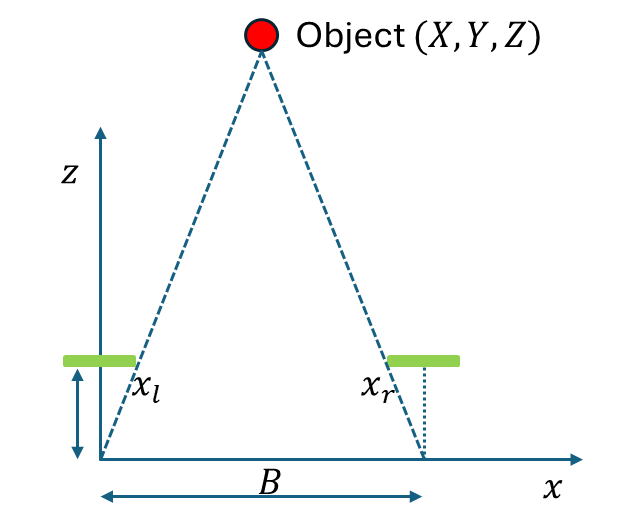

Let a world point have coordinates $(X,Y,Z)$ expressed relative to the left camera center. Using a common focal length $f$ (in pixels), the image x-coordinates (assuming principal points aligned) are: $x_L=\frac{f\,X}{Z}, \; x_R=\frac{f\,(X-B)}{Z}.$ Let the **disparity **$d$ as the horizontal shift between corresponding image points: $d=x_L-x_R=\frac{f\,B}{Z}$. Hence the depth is given by $Z=\frac{f\,B}{d}$. Depth is *inversely proportional* to disparity, for a fixed disparity error, depth accuracy improves with larger baseline $B$. Although increasing $B$ can cause some scene points to fall outside the other camera’s field of view (occlusions). 

**CoppeliaSim Code Example**

**Environment Setup and Scene Configuration**: This block prepares MATLAB to communicate with CoppeliaSim and ensures the RGB + Depth camera scene is correctly located. It builds all required paths and validates the setup before starting perception.

 
clc; clear; close all;

%% 1. CONFIGURATION & SETUP (Dynamic)

% --- Dynamic Path Configuration ---
% Get the installation root from the environment variable
coppeliaRoot = getenv('COPPELIA_ROOT');

% Safety check: Ensure the variable exists
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

% Dynamically build the path to the API and Executable
apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

% Add the API path to MATLAB
if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene File Setup ---
if matlab.desktop.editor.isEditorAvailable
    % This grabs the full path of the currently open Live Script
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    % Fallback: use the current working directory if not running from editor
    currentScriptPath = pwd;
end

% Construct the scene path 
% Target: .../scenes/Depth_camera implementation/depth_cam.ttt
sceneFile = fullfile(currentScriptPath, 'scenes', 'Depth_camera implementation', 'depth_cam.ttt');

% --- Basic Checks ---
if ~isfile(exePath)
    error('CoppeliaSim executable not found: %s', exePath);
end
if ~isfile(sceneFile)
    warning('Scene file not found at: %s', sceneFile);
else
    disp(['Scene file found: ', sceneFile]);
end


%% 2. LAUNCH COPPELIASIM
disp('Launching CoppeliaSim...');
system(['start "" "' exePath '"']);

% Wait for GUI to open
pause(4); 

% Connect to RemoteAPIClient with timeout
timeout = 30; 
tic;
client = [];
disp('Attempting to connect to API...');

while toc < timeout
    try
        client = RemoteAPIClient(); 
        break
    catch
        pause(0.5);
    end
end

if isempty(client)
    error('Could not create RemoteAPIClient within %d seconds. Check if CoppeliaSim launched correctly.', timeout);
end

sim = client.getObject('sim');


%% 3. SIMULATION ROUTINE
try
    disp('Loading scene...');
    % Only load if the file actually exists
    if isfile(sceneFile)
        sim.loadScene(sceneFile);
    end
    pause(1);

    % -------------------------
    % Get handles
    % -------------------------
    % Ensure these match your scene hierarchy
    cam_rgb    = sim.getObject('/PioneerP3DX/kinect/rgb');
    cam_depth  = sim.getObject('/PioneerP3DX/kinect/depth');
    leftMotor  = sim.getObject('/PioneerP3DX/leftMotor');
    rightMotor = sim.getObject('/PioneerP3DX/rightMotor');

    % -------------------------
    % Move robot forward
    % -------------------------
    sim.setJointTargetVelocity(leftMotor,  2);
    sim.setJointTargetVelocity(rightMotor, 2);

**Visualization Setup (RGB + Depth):** Creates two display windows: one for RGB images and one for depth data. This allows students to compare appearance vs distance information.

    % -------------------------
    % Create Figures
    % -------------------------
    % RGB Figure
    hFigRGB = figure('Name','RGB Camera', 'NumberTitle', 'off');
    hImgRGB = imshow(zeros(480, 640, 3, 'uint8')); % Default Kinect res
    title('RGB Image');

    % Depth Figure
    hFigDepth = figure('Name','Depth Camera', 'NumberTitle', 'off');
    hImgDepth = imshow(zeros(480, 640), [0, 1], 'InitialMagnification','fit');
    colormap('jet');
    colorbar;
    title('Depth Image (0 = Near, 1 = Far)');

    disp('Starting simulation...');
    sim.setStepping(true); 
    sim.startSimulation();
  

**RGB Image Processing (Visual Perception)**: Reads raw RGB image data and converts it into a properly formatted image. This includes reshaping and correcting orientation. Then, reads depth values and converts them into a 2D depth map. Each pixel represents distance from the camera.

  
    % -------------------------------------------------
    % SENSOR LOOP
    % -------------------------------------------------
    for i = 1:200
        
        % ===========================
        % 1. PROCESS RGB
        % ===========================
        [img, res] = sim.getVisionSensorImg(cam_rgb);
        
        if ~isempty(img)
            % Resolution handling
            if iscell(res), res = double(cell2mat(res)); end
            w = res(1); h = res(2);

            % Data conversion
            if iscell(img), img = cell2mat(img); end
            img = uint8(img); % Raw is 0-255, do not multiply by 127.5

            try
                % Reshape [3, W, H] -> Permute [H, W, 3] -> Flip
                img = reshape(img, [3, w, h]);
                img = permute(img, [3 2 1]); 
                img = flipud(img);
                
                if ishandle(hImgRGB)
                    set(hImgRGB, 'CData', img);
                end
            catch
                % ignore reshape errors during startup
            end
        end

        % ===========================
        % 2. PROCESS DEPTH
        % ===========================
        % Flag '1' requests the data as a table of floats (no unpacking needed)
        [depth, resD] = sim.getVisionSensorDepth(cam_depth, 1);
        
        if ~isempty(depth)
            % Resolution handling
            if iscell(resD), resD = double(cell2mat(resD)); end
            wD = resD(1); hD = resD(2);
            
            % Data conversion
            if iscell(depth), depth = cell2mat(depth); end
            
            try
                % Depth comes as 1D array, reshape to [W, H]
                % Note: Depth usually doesn't have the "3" color channel
                depth = reshape(depth, [wD, hD]);
                
                % Fix Rotation: Transpose + Flip
                depth = depth';   % Equivalent to permute(..., [2 1])
                depth = flipud(depth);
                
                if ishandle(hImgDepth)
                    set(hImgDepth, 'CData', depth);
                end
            catch
                 % ignore reshape errors
            end
        end
        
        drawnow;
        
        % Check if user closed figures
        if ~ishandle(hFigRGB) || ~ishandle(hFigDepth)
            break; 
        end
        
        sim.step();
        
        % Check if simulation stopped
        if sim.getSimulationState() == sim.simulation_stopped
            break;
        end
    end

    % -------------------------
    % STOP & CLEANUP
    % -------------------------
    disp('Stopping...');
    sim.stopSimulation();
    pause(1);
    
    sim.quitSimulator();
    disp('Done.');

catch ME
    % -----------------------------
    % CLEANUP ON ERROR
    % -----------------------------
    warning('An error occurred: %s', ME.message);
    try
        if exist('sim', 'var') && ~isempty(sim)
            sim.stopSimulation();
            sim.quitSimulator();
        end
    catch
        % ignore cleanup errors
    end
    rethrow(ME);
end

# Computer vision

## **Fundamentals of Image Processing**

**Images as signals: **An image is a sampled two-dimensional signal. We denote the (grayscale) image by $I(x,y), \; \; x\in {\{1,\ldots,W\},y\in \{1,\ldots,H\},$ where $x,y$ are spatial coordinates and the scalar value $I\left(x,y\right)$ is the image intensity (gray level) at that location. A color image can be treated as three channels $I_R,I_G,I_B$ or converted to other color spaces (HSV, Lab) when useful. 

**Linear spatial filtering: **A **linear spatial filter** uses a small kernel (mask) $w(s,t)$ of size $m\times n$ that is applied at every pixel to produce an output image $J(x,y).$ The filter can be expressed as $J(x,y)=\sum_{s=-a}^a\sum_{t=-b}^b w(s,t)I(x+s,\;y+t),$ with $m=2a+1,\;n=2b+1.$ The filter $w$ is also called kernel, mask or window. A more popular equivalent linear filter is known as convolution which is given by $J(x,y)=\sum_{s=-a}^a\sum_{t=-b}^b w(s,t)I(x-s,\;y-t)  = w(x,y)\ast I(x,y)$. If $w$ is symmetric $
(w(s,t)=w(-s,-t))$ correlation and convolution give identical results.

**Smoothing (lowpass) filters: **Smoothing reduces high-frequency noise and stabilizes derivative estimates (important before computing gradients or second derivatives). 

- Box (mean) filter: A simple average kernel of size $k\times k:$ $w(s,t)= \frac{1}{k^2} \; \text{for} \; s,t\in {-\frac{k-1}{2},\ldots,\frac{k-1}{2}}.$ 

- Gaussian filter: The isotropic Gaussian kernel (standard deviation $\sigma $): $G_\sigma (x,y) = \frac{1}{2\pi \sigma ^2} exp(- \frac{x^2 + y^2}{2\sigma ^2})$.

**Edge detection: **Edges and corners are locations with large local intensity change. The first derivatives provide gradient components: $I_x = \frac{\partial I}{\partial x},I_y= \frac{\partial I}{\partial y}$. The gradient magnitude and orientation is given by $G= \sqrt{I_x^2+I_y^2}$ , $\theta =atan2(I_y,I_x).$ In practice, derivatives are computed by convolving with derivative kernels (often after or combined with Gaussian smoothing). Edges are curves along which intensity changes abruptly. Robust edge detection needs (i) smoothing, (ii) derivative computation and (iii) localization and thinning. 

- **The Canny edge detector: **John Canny formulated edge detection as an optimization balancing signal-to-noise, localization, and single response. The standard Canny pipeline:

- **Smooth** image with Gaussian $G_\sigma$.

- **Compute gradients** $I_x,I_y$ and magnitude $G$ and orientation $\theta$.

- **Non-maximum suppression**: thin edges by keeping gradient magnitude local maxima along the gradient direction.

- **Hysteresis thresholding**: two thresholds $T_\text{low}<T_\text{high}$, strong edges ($>T_\text{high}$) are kept; weak edges (between thresholds) are kept only if connected to strong edges. This reduces spurious responses while preserving thin edges.

**Adaptive / dynamic thresholding: **Fixed thresholds fail under varying illumination. Two practical approaches:

- **Percentile / top-N selection:** compute histogram of gradient magnitudes and pick a threshold such that the top-k strongest edge pixels remain (useful when the number of meaningful edges per image is roughly constant).

- **Local adaptive threshold:** compute thresholds locally per image tile (Sauvola / Niblack for intensity thresholding) or scale thresholds with local contrast.

**Hough transform: **The Hough transform maps each edge point $(x,y)$ to a sinusoid in the $(\rho ,\theta )$ accumulator space. Peaks in the accumulator correspond to lines with many supporting edge pixels. Hough transform involves the following steps:

- Initialize accumulator $A(\rho ,\theta )=0.$

- For each edge pixel $(x,y)$, and for each sampled $\theta $: compute $\rho $ and increment $A(\rho ,\theta )$.

- Find accumulator peaks above a vote threshold → returned lines.

- Optionally refine via least squares on the supporting points.

## Image similarity measures

Area-based matching compares small patches (windows) between two images. Let two patches be $P$ from image $I$ centered at $(u,v)$ and $Q$ from image $J$ centered at $(u\prime ,v\prime ),$ both of size $(2a+1)\times (2b+1).$ The similarity is computed using gray intensity levels of two patches. Some of the the popular criteria are:

- Sum of Absolute Differences (SAD): $\sum_{k=-a}^a\sum_{l=-b}^b |I(u+k,v+\ell )-J(u\prime +k,v\prime +\ell )|.$

- Sum of Squared Differences (SSD): $\sum_{k,l}(I(u+k,v+\ell )-J(u\prime +k,v\prime +\ell ))^2.$

- Normalized Cross Correlation (NCC): $\frac{\sum_{k,l}(I_{k\ell }-\mu _I)(J_{k\ell }-\mu _J)}{\sqrt{\sum_{k,l}(I_{k\ell }-\mu _I)^2} \sqrt{\sum_{k,l}(J_{k\ell }-\mu _J)^2}}$,where $\mu 
_I
	

,\mu 
_J
	
$are patch means. NCC ranges from −1 to 1 (1 = perfect positive correlation), often used when illumination differs (affine intensity changes).

## Feature extraction

Feature extraction is the deliberate process of transforming raw sensor measurements into higher-level, more compact, and more reliable percepts that a robot can use for mapping, localization, planning, and decision making. Sensors are noisy and produce overwhelming amounts of data. Feature extraction gives you:

- **Robustness**: reduce sensitivity to single noisy measurements by producing stable, repeatable cues.

- **Compression**: represent the environment compactly so downstream algorithms run faster and scale.

- **Abstraction**: produce semantically useful elements (corners, lines, objects) for mapping and planning.

- **Interoperability**: combine data from different sensors (vision, lidar, sonar) through features in a common representation.

Robots use features selectively. For *emergency stop* you might use raw range readings. For *long-term mapping* you use feature-based SLAM. For *local obstacle avoidance* you might fuse features into an occupancy grid. The perceptual pipeline commonly follows: `sensor readings → preprocessing → feature extraction → geometric/semantic interpretation → model update / action`

A **feature** is a detectable, repeatable, and describable element in sensor data. We classify features by abstraction:

- **Low-level geometric features (primitives)** — points, corners, line segments, planes, blobs, circles.

- **Mid-level features** — small objects or persistent patterns (door handles, signboards, fiducials).

- **High-level semantic features (objects/places)** — chairs, doorways, rooms, semantic labels for maps.

**Typical features by sensor modality**

**Vision (cameras)**

- **Corners / points**: Harris, Shi-Tomasi, FAST. Great for tracking and triangulation.

- **Blobs / region features**: SIFT, SURF, MSER — better scale estimation and distinctiveness.

- **Line segments**: useful indoors for walls/ceilings (LSD, EDLines).

- **Descriptors**: SIFT, SURF (float); ORB, BRIEF, BRISK, FREAK (binary) — choose float for distinctiveness, binary for speed.

**Range sensors (lidar, depth cameras)**

- **Planar patches / planes**: dominant in man-made environments.

- **Edges / corners**: laser scan corner extraction (e.g., sharp change in beam distance).

- **Geometric primitives**: cylinders, poles, doors (fitted with RANSAC).

**Sonar / low-resolution sensors**

- **Large obstacles / surface sectors**: use coarse occupancy or sectors; feature extraction is limited by resolution.

# **Quiz**

**1) **A robot consistently measures the distance to a wall as $2.05 m, even though the actual distance is exactly 2.00 m. What type of error is this, and how can it typically be addressed?

"Quantization Error"

switch ans
    case "One"
        disp("");
        % Add specific code for 'One' here
        
    case "Two"
        disp(" ");
        % Add specific code for 'Two' here
        
    case "Quantization Error"
        disp("Right Answer");
        % Add specific code for 'Three' here
        
    otherwise
        disp("Wrong Answer.");
end

2) You are programming a robot to track fast-moving objects, but the resulting images are blurry. Which camera parameter should you primarily adjust to reduce this motion blur?


"Focal Length"
switch ans
    case "One"
        disp("");
        % Add specific code for 'One' here
        
    case "Two"
        disp(" ");
        % Add specific code for 'Two' here
        
    case "Shutter Speed"
        disp("Right Answer");
        % Add specific code for 'Three' here
        
    otherwise
        disp("Wrong Answer.");
end

**3) **In stereo vision, a wider baseline improves depth accuracy for which targets?

"Distant objects"
switch ans
    case "Distant objects"
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

# **Exercise**

1) Make a coppeliaSim scene with a differential drive robot attached with a proximity sensor and a vision sensor.

2)  Position the robot such that its Proximity Sensor is exactly 1.00 meters away from a wall or object.

3) Write a MATLAB script to record 100 discrete distance readings from the sensor while the robot is stationary.

4) Calculate Mean and Standard Deviation.

5) Determine Accuracy

6) Plot a Histogram of the sensor readings. Does it look like a Gaussian distribution?

7)  Acquisition: Retrieve a single frame from the robot's Vision Sensor in MATLAB.

8) Convert the RGB image to Grayscale.

9)  Apply the Canny Edge Detector to the grayscale image.

10) Implement a simple algorithm to find the "Red" object in the scene.

11) Draw a crosshair or bounding box on the original image at the calculated centroid.